# **IO3xx Quadrature - Speed Filter**

This example demonstrates the quadrature code module functionalities using a quadrature encoder **QAE 3** and a quadrature decoder **QAD 5*****,*** which are both on the same I/O module connected to a loopback. This example illustrates the QAD speed filter in detail.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports at least **1 x QAD channel** and **1 x QAE channel**

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, data are sent from the QAE to the QAD. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file (bitstream) used. 

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect theses pins with jumper wires. 

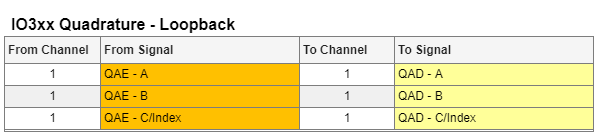

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Quadrature_SpeedFilter';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

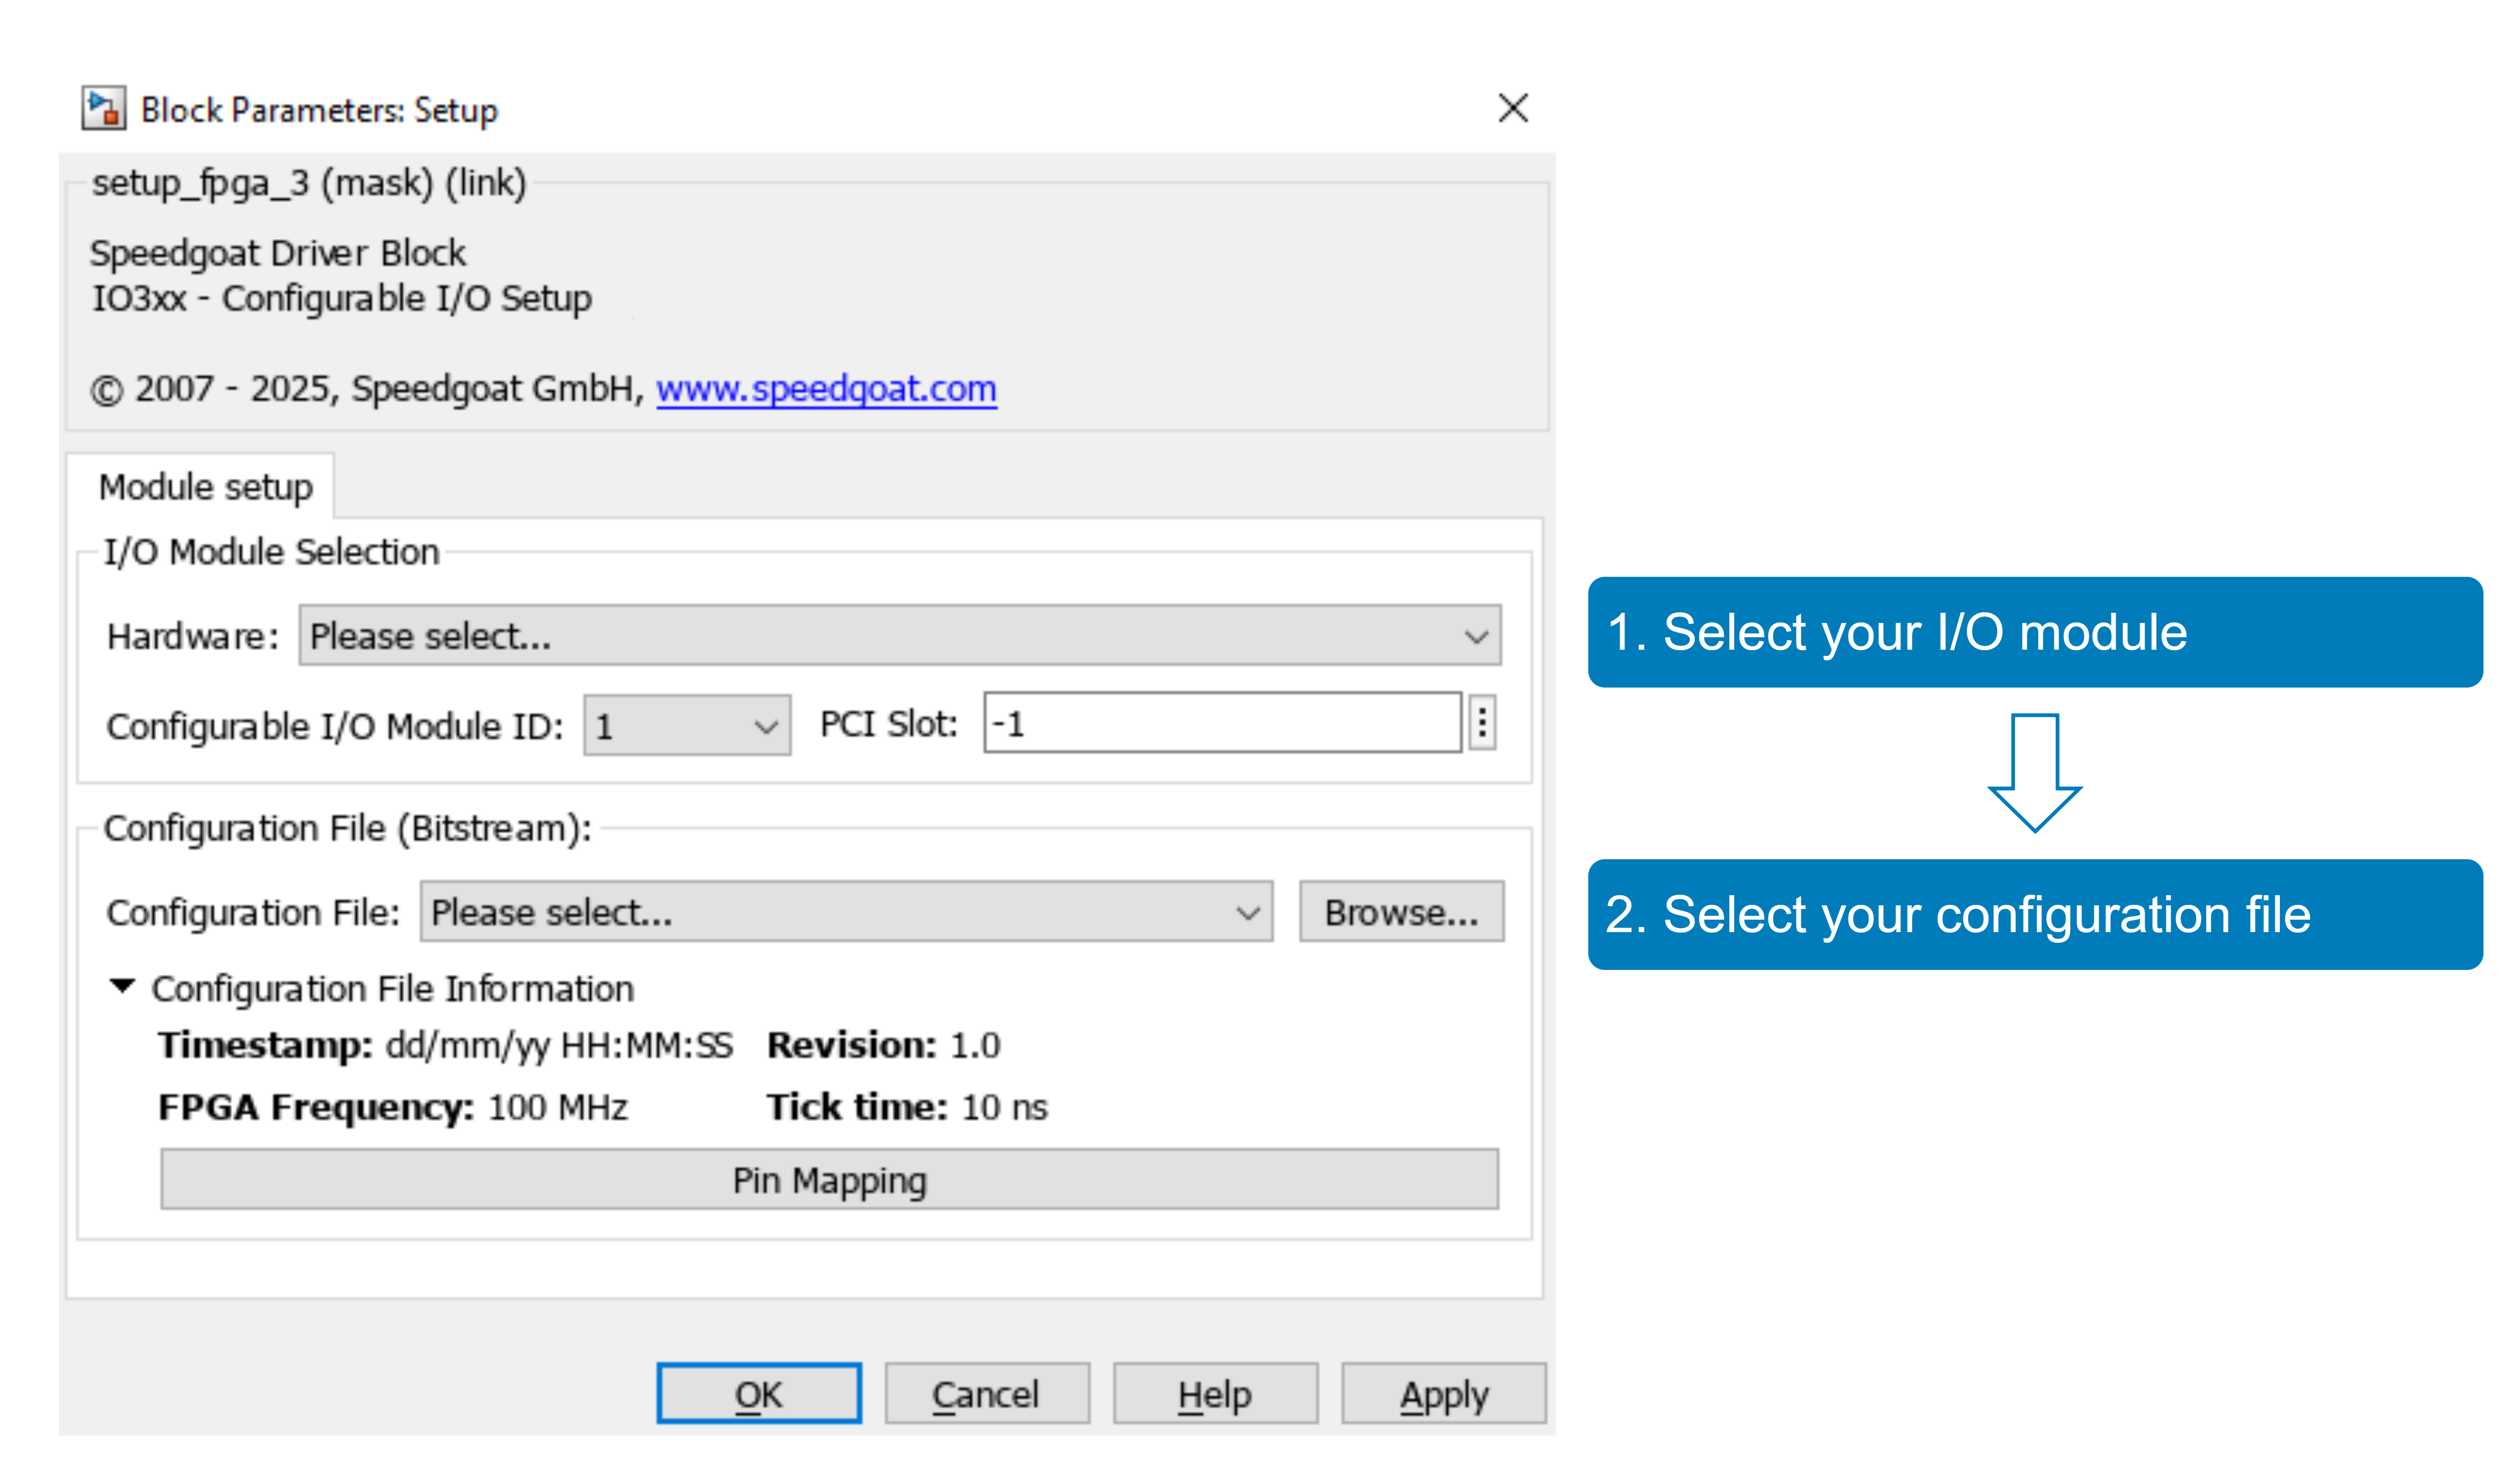

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### QAE Signal generation

In the model, the QAE generates qadrature signals as depicted in the following image (Example with 8 Slots per turn):

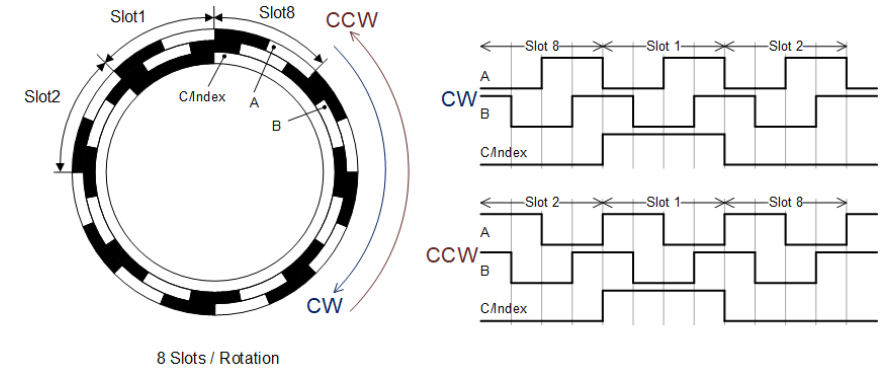

### QAD Signal analyzing

The QAD analyzes the data as depicted in the following image (Example with 4 Slots per turn):

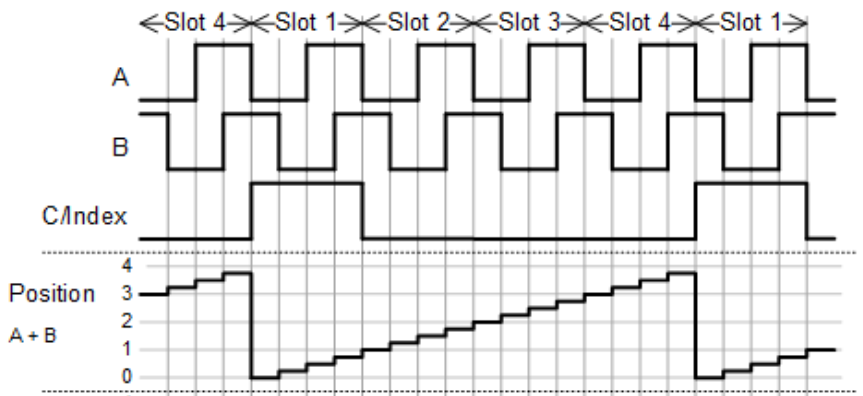

### QAD Speed Measurement

The QAD measures the speed of the signal by counting the time between the A- and B-Signal edges. This time is the base to calculate the speed.

### Model Behavior

In the example model, both the [Quadrature Encoder (QAE)](https://www.speedgoat.com/help/slrt/page/io_main/refentry_quadrature_encoder_v3) and the [Quadrature Decoder (QAD)](https://www.speedgoat.com/help/slrt/page/io_main/refentry_quadrature_decoder_v5) block are set to 8 slots per turn. The QAD block is configured to use the A and the B signal to detect the position. The index (signal "C/Index" described in the above image) is used to reset the detected position to 0.

In this model, the QAE Block is fed with a constant value on the **Speed [rpm]** input. To show the impact of the QAD speed-filter, the speed is set to a high value. The following image explains the reason for this:

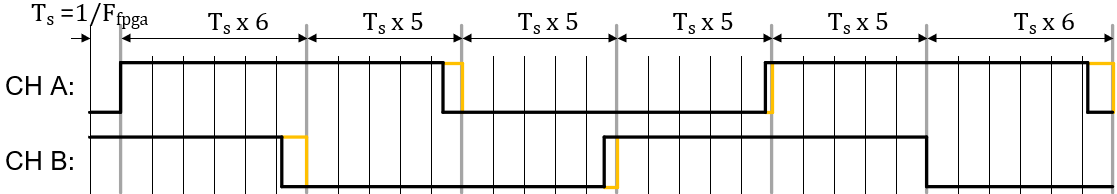

The QAD measurements are placed in the FPGA which runs at a specified frequency $F_{\textrm{fpga}}$. This means that the timing measurement precision is directly related to the FPGA sampling time $\textrm{Ts}=\frac{1}{F_{\textrm{fpga}} }$.

The above image shows the situation of this example for an FPGA Frequency of $75\;\textrm{MHz}$. One single signal (either the A- or B- signal) has a periodicity between $\textrm{Ts}*20$ and $\textrm{Ts}*21$ (for this example, we have a time slightly above 20 FPGA ticks). Since the number of slots are set to 8 and the speed unit is $\textrm{rpm}$ the applied speed in the model is 


$$\frac{75\;\textrm{MHz}}{20\;*8\;}*60\frac{s}{\min }=28\ldotp 125{\;e}^6 \;\textrm{rpm}$$


To make the period a bit above $20$ FPGA ticks, we set the speed value to $28e^6 \;\textrm{rpm}$. This results in a signal period of approx. $20\ldotp 1$FPGA ticks.

Since also the QAE unit is based on the same FPGA timing, the generated quadrature signal is not perfectly constant. A real encoder may have a constant period but cannot be exactly measured by the FPGA. In the end, both, the FPGA generated signal in this example or a real encoder, have the same speed.

The final effect (quadrature signals generated from FPGA or a real encoder) is a slightly different time measurements between the A- and B- Signal edges. As depicted in the above drawing, the time-measurement of the quadrature signal in this example is sometimes $\textrm{Ts}*6$ and sometimes $\textrm{Ts}*5$. In case every single time-sample is used to calculate the speed, this results in different speed measurement, even if the quadrature signal itself is on a constant speed.

Using the speed-value filter of the QAD unit helps minimizing this effect. The speed filter calculates the average of a settable number of single measurements. In this example, the filter width can be adjusted by a signal input **Speed Filter Width** on the QAD block.

In this example, the Speed Filter Width is initially set to 10 samples and from 4.0s of the simulation continuously increased. Note that the maximum speed filter width is 256, the value is limited in the QAD unit.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 
tg.setStopTime(10);
% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  
% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

## Check the Results

To check the loopback is working as expected, open the Simulink scope that is connected to the following signals:

- QadSpeedFilterWidth: This is the number of measured speed-samples which are moving-averaged for the speed measurement

- QadSpeed: This is the calculated speed of the QAD unit

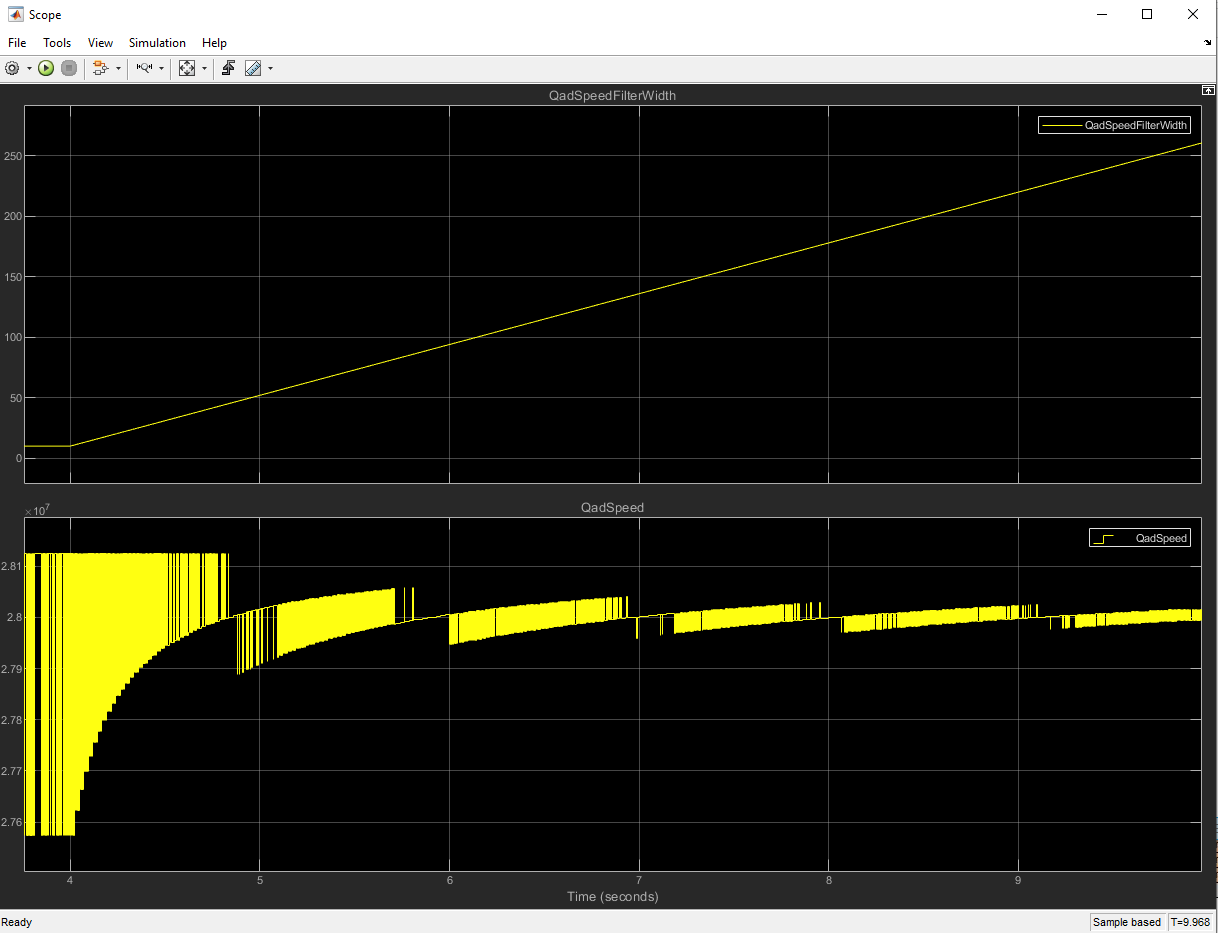

As described above, the exact speed of $28e^6 \;\textrm{rpm}$ cannot be exactly measured by the FPGA. However, if we increase the moving average width of the speed filter, the measurements get more precise.

## Additional References

The following links describe the QAE and QAD and all it's parameters in details:

- [Quadrature documentation (Encoder v3, Decoder v5) and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_quadrature)